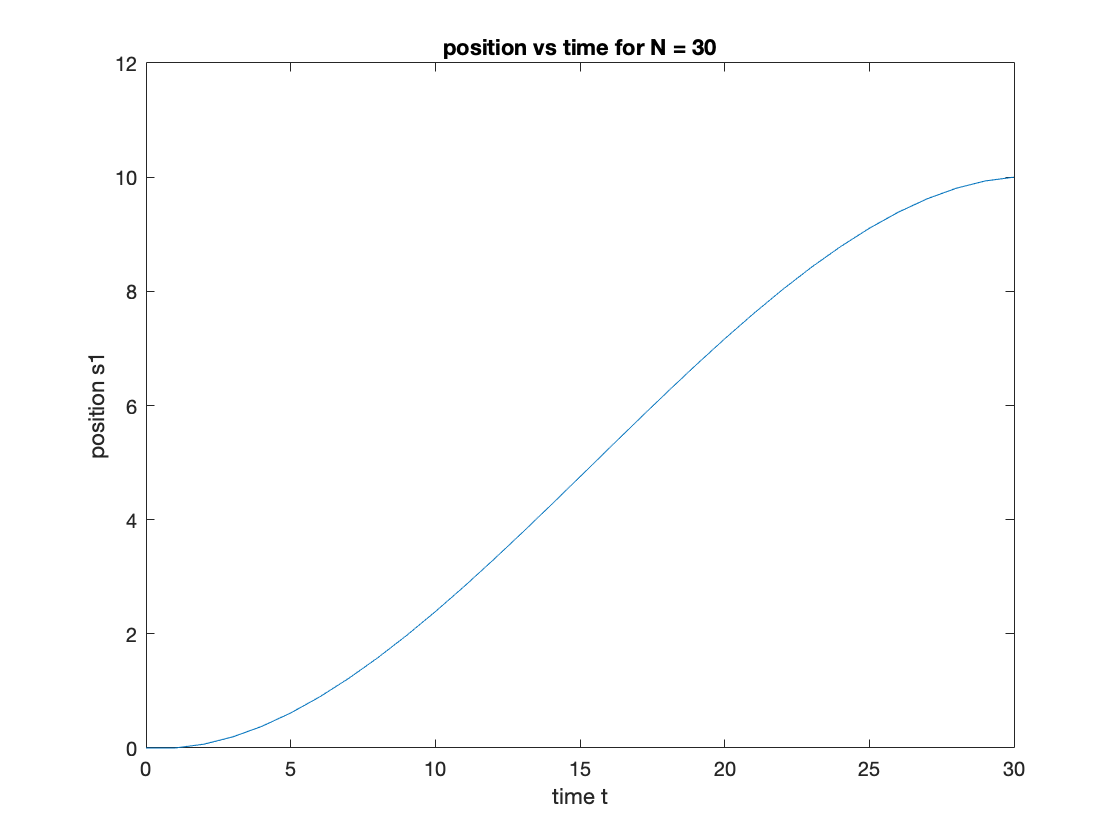

% 10.1b

N = 30;

A = [1 1; 0 0.95];
b = [0; 0.1];

C = zeros(2, N);

bi = b;
for i = N:-1:1
	C(:,i) = bi;
	bi = A * bi;
end

d = [10; 0];

[Q, R] = qr(C', 0);
u = Q * (R' \ d);

s = zeros(2, N);
for i = 1:N
    s(:,i + 1) = A * s(:,i) + b * u(i);
end

plot(0:N, s(1,:));
xlabel('time t');
ylabel('position s1');
title('position vs time for N = 30');

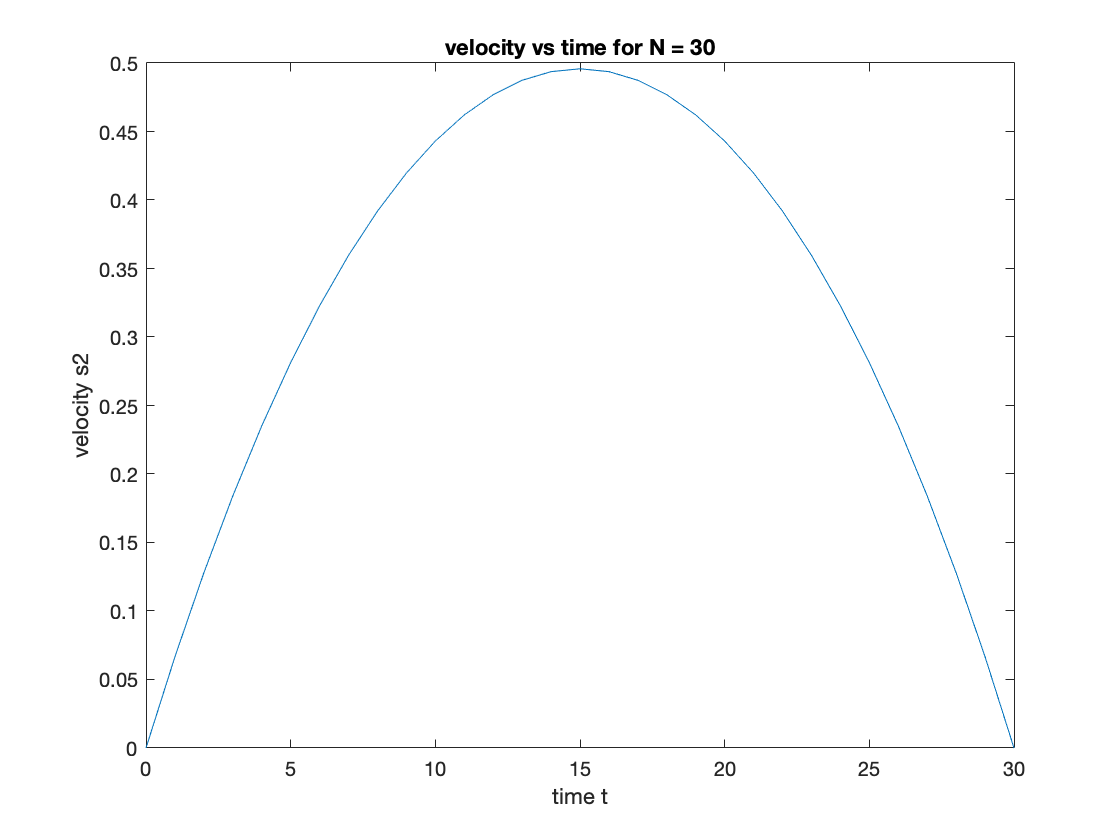

plot(0:N, s(2,:));
xlabel('time t');
ylabel('velocity s2');
title('velocity vs time for N = 30');

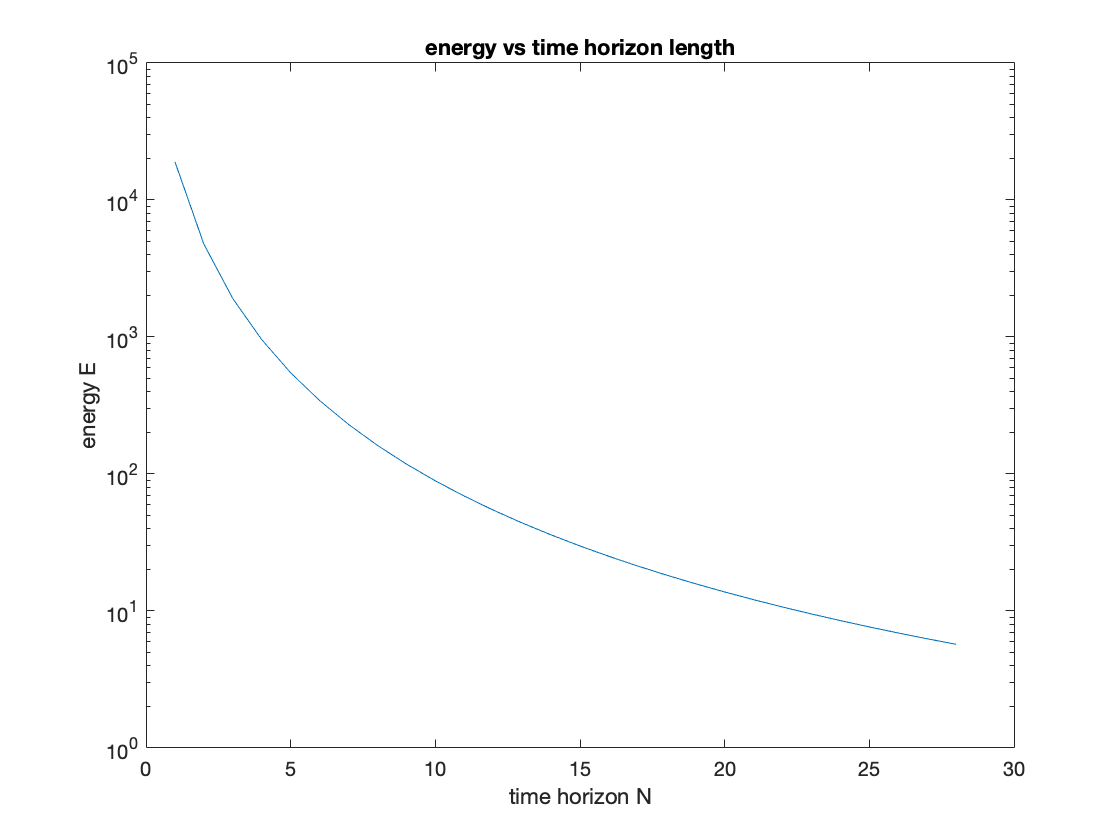

% 10.1c

E = zeros(28, 1);
for N = 2:29
    A = [1 1; 0 0.95];
    b = [0; 0.1];
    
    C = zeros(2, N);
    
    bi = b;
    for i = N:-1:1
    	C(:,i) = bi;
    	bi = A * bi;
    end
    
    d = [10; 0];
    
    [Q, R] = qr(C', 0);
    u = Q * (R' \ d);
    
    E(N - 1) = norm(u)^2;
end

semilogy(1:28, E);
xlabel('time horizon N');
ylabel('energy E');
title('energy vs time horizon length');